#  ENME462 Studio 10 Root Locus Compensator Design

by Xie Zheng

Section 0101 W 1:00PM - 2:50PM; Section 0103 F 10:00AM - 11:50AM

Github: [https://github.com/XieGT/Control_Studios](https://github.com/XieGT/Control_Studios)

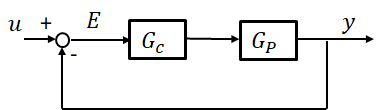

**Close-loop transfer function:**


$$T(s)=\frac{G_c(s)G_p(s)}{1+G_c(s)G_p(s)}$$


**Characteristic equation :**


$$1+G_c(s)G_p(s)=0$$


Magnitude condtion:


$$|G_c(s)G_p(s)|=1$$


Phase condition:


$$\angle G_c(s)G_p(s)=180^o$$


## Response:

***1) Transient response (unity step input)***

First order system $T(s)=\frac{a}{s+a}=\frac{1}{\tau s+1}$

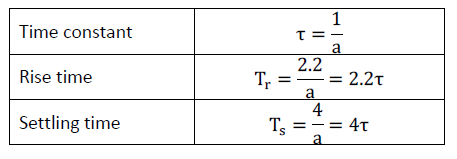

Second order system $T(s)=\frac{\omega_{n}^{2}}{s^2+2\zeta \omega_ns+\omega_{n}^{2}}$

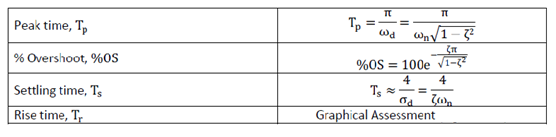

***2) Steady-state error (unity feedback)***

Position constant: $K_p=\lim_{s\rightarrow0}G(s)$        Velocity constant: $K_v=\lim_{s\rightarrow0}sG(s)$        Acceleration constant: $K_a=\lim_{s\rightarrow0}s^2G(s)$

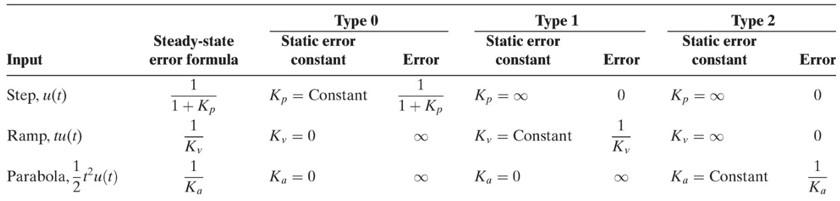

## Compensators: 

**1) Transient Response Compensators**

*i) ****PD**** compensators: *


$$G_c(s)=K_P+K_Ds=K_D(s+K_P/K_D)$$


PD compensator improves the ransient response via *re-shaping* the original system's root locus. An additional zero provides 1 DoF to adjust the root locus angle condtion.

*ii) ****Lead**** compensators*


$$G_c(s)=K\frac{s+z_c}{s+p_c}, \qquad |p_c| <|z_c|$$


Lead compensator improves the transient response via *re-shaping* the original system's root locus. An additional zero/pole pair is placed at a location so that the root locus angle condition can be satisfied at the target closed-loop poles.

**2) Steady-state error Compensators **

*i) ****PI**** compensators*


$$G_c(s)=K_P+\frac{K_I}{s}=\frac{K_P(s+K_i/K_P)}{s}$$


PI compensator adds a pole at he origin and a zero close to the origin to prevent the additional pole from significantly distorting the shape of the original system's root locus. 

ii) **Lag** compensators

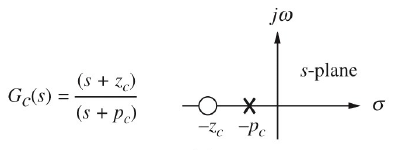

Lag compensator increase the statc error constants, without distorting the shape of the original systems' root locus.

## **Example 1**

The figure below shos a two-tank system. The liquid inflow the upper tank can be controoled using a valve and is represented by $F_0
$. The upper tank's outflow equals the lower tank's inflow and is represented by $F_1$. The outflow of the lower tank is $F_2$. The control design objective is to control the liquid level in the lower tank $y(t)$

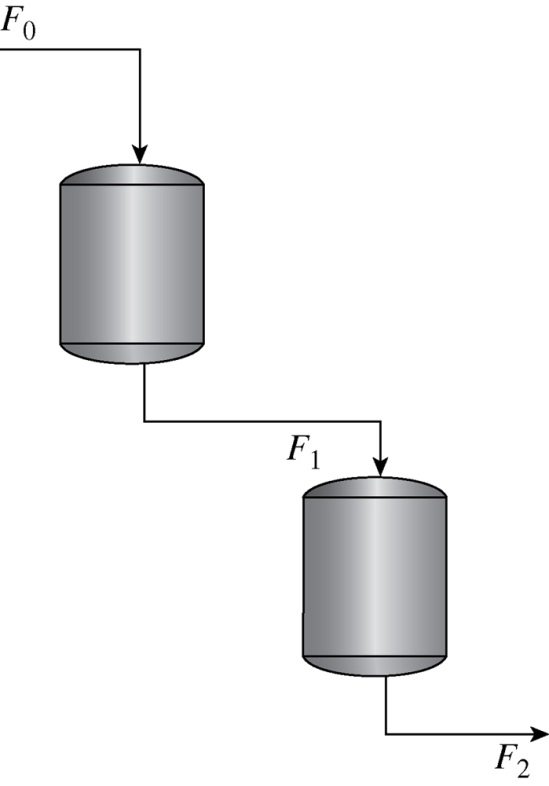

The open-loop transfer function 


$$G(s)=\frac{Y(s)}{F_0(s)}=\frac{a_2a_3}{s^2+(a_1+a_4)s+a_1a_4}$$


where $a_1=0.04, \quad a_2=0.0187, \quad a_3=1, \quad a_4= 0.227$

i) Consider the system in a unity feedback configuration. Plot the root locus and determine the steady state error.


$$K_p=\lim_{s \rightarrow0}G(s)=\lim_{s \rightarrow0}\frac{a_2a_3}{s^2+(a_1+a_4)s+a_1a_4}=\frac{a_2a_3}{a_1a_4}=2.0595\\
ess=\frac{1}{1+K_p}=0.3269$$


a = [0.04, 0.0187, 1, 0.227];
s = zpk('s');
G = a(2)*a(3)/(s^2 + (a(1)+a(4))*s + a(1)*a(4))


G =
 
        0.0187
  ------------------
  (s+0.04) (s+0.227)
 
Continuous-time zero/pole/gain model.



Kp = a(2)*a(3)/(a(1)*a(4))

Kp = 2.0595

ess = 1/(1+Kp)

ess = 0.3269

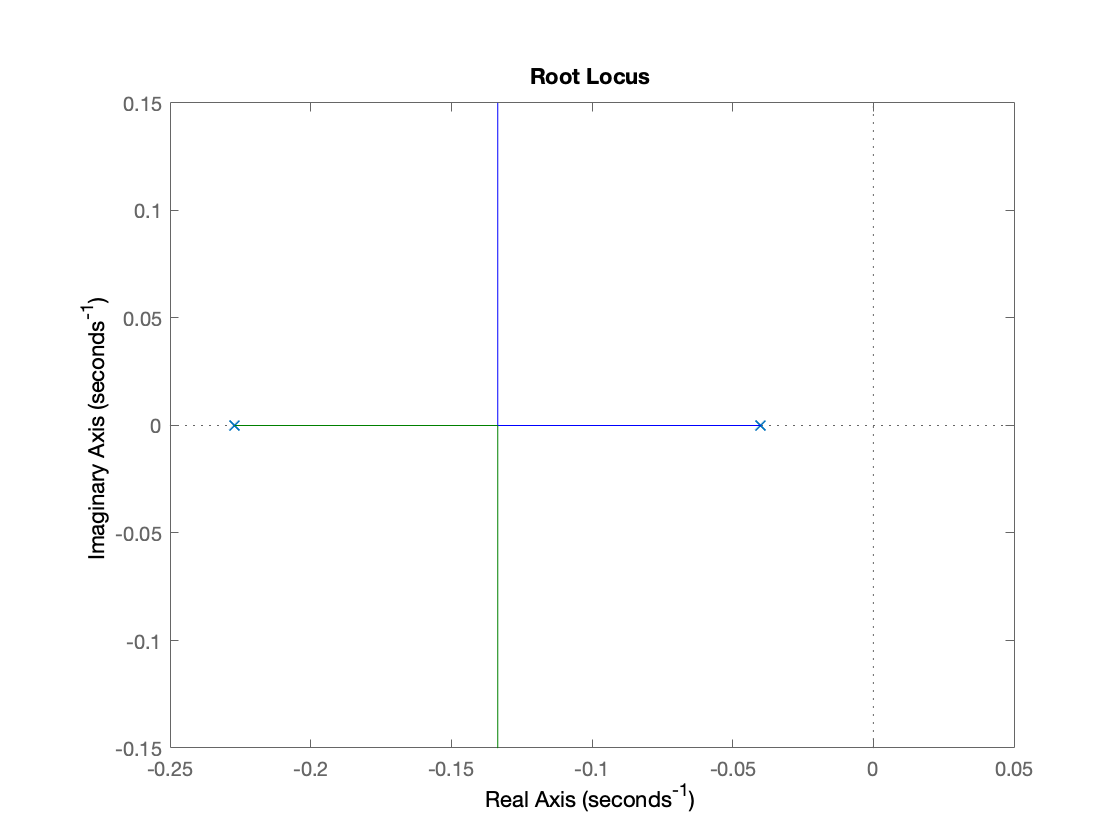

rlocus(G)

T_origin = feedback(G,1)


T_origin =
 
           0.0187
  ------------------------
  (s^2 + 0.267s + 0.02778)
 
Continuous-time zero/pole/gain model.



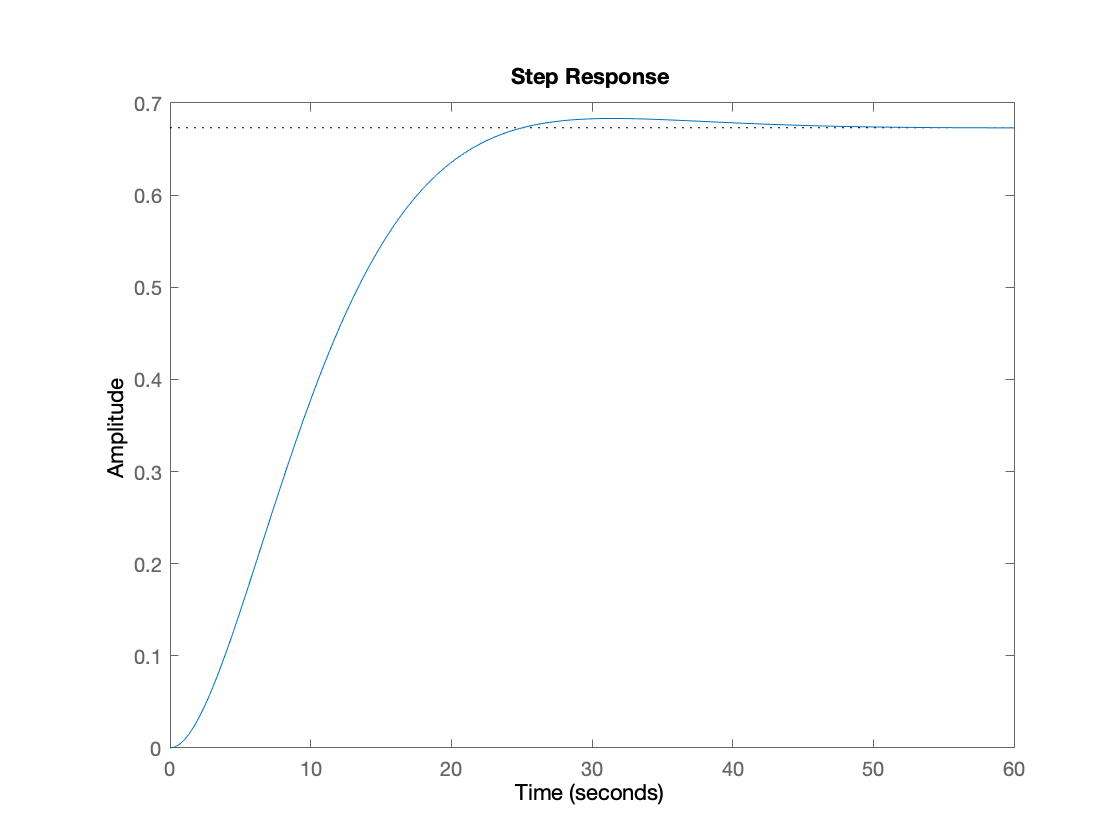

step(T_origin)

ii) Design a lag compensator to yield a 10% steady-state error to step inputs.

Goal:              $\hat{ess}=\frac{1}{1+\hat{K}_p}=0.1 \rightarrow \hat{K}_p=9$

Lag compensator $G_c(s)=\frac{s+z_c}{s+p_c}$


$$K_p=\lim_{s\rightarrow0}G(s)G_c(s)=\frac{a_2a_3}{a_1a_4}\cdot\frac{z_c}{p_c}=\hat{K}_p\\
\frac{z_c}{p_c}=\hat{K}_p/(\frac{a_2a_3}{a_1a_4})=4.3701$$


Assume $p_c=0.01$ then $z_c=0.0437$

hat_Kp = 9;
zc_div_pc = hat_Kp / Kp

zc_div_pc = 4.3701

pc = 0.01;
zc = pc * zc_div_pc;
Gc = (s+zc) / (s+pc)


Gc =
 
  (s+0.0437)
  ----------
   (s+0.01)
 
Continuous-time zero/pole/gain model.



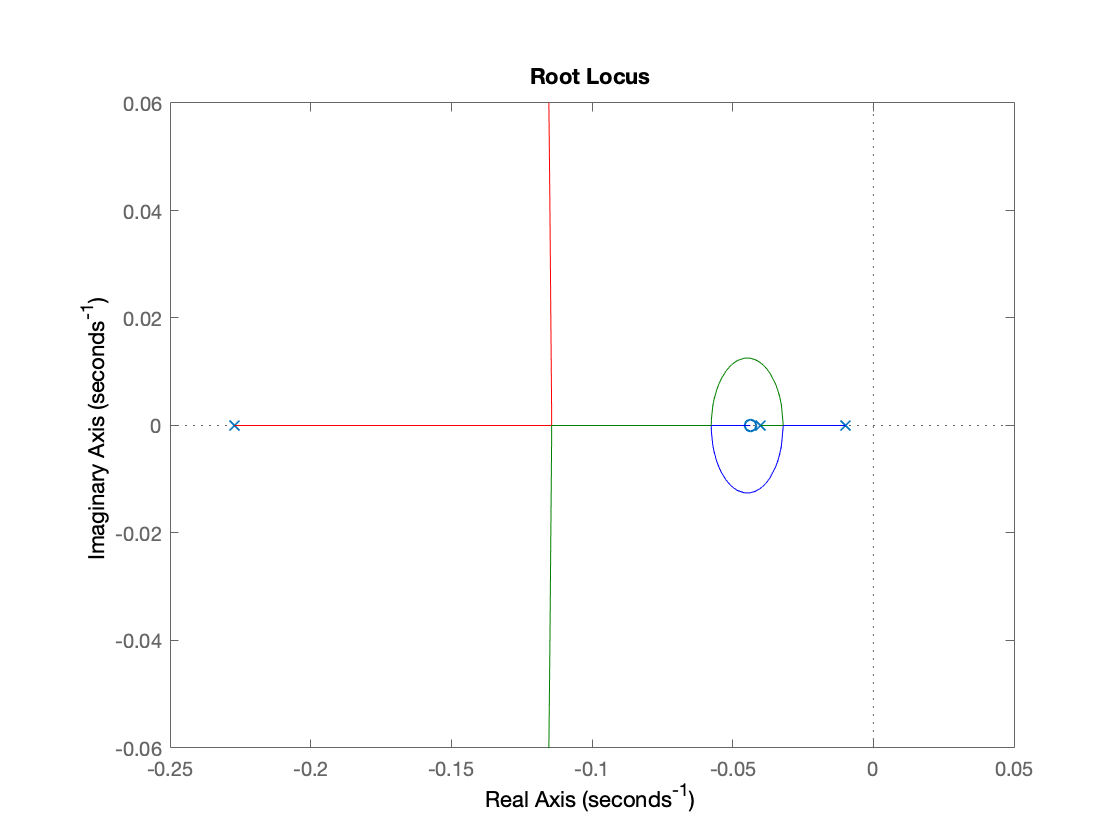

rlocus(Gc*G)

iii) Plot the step response for i) and ii) on the same plot.

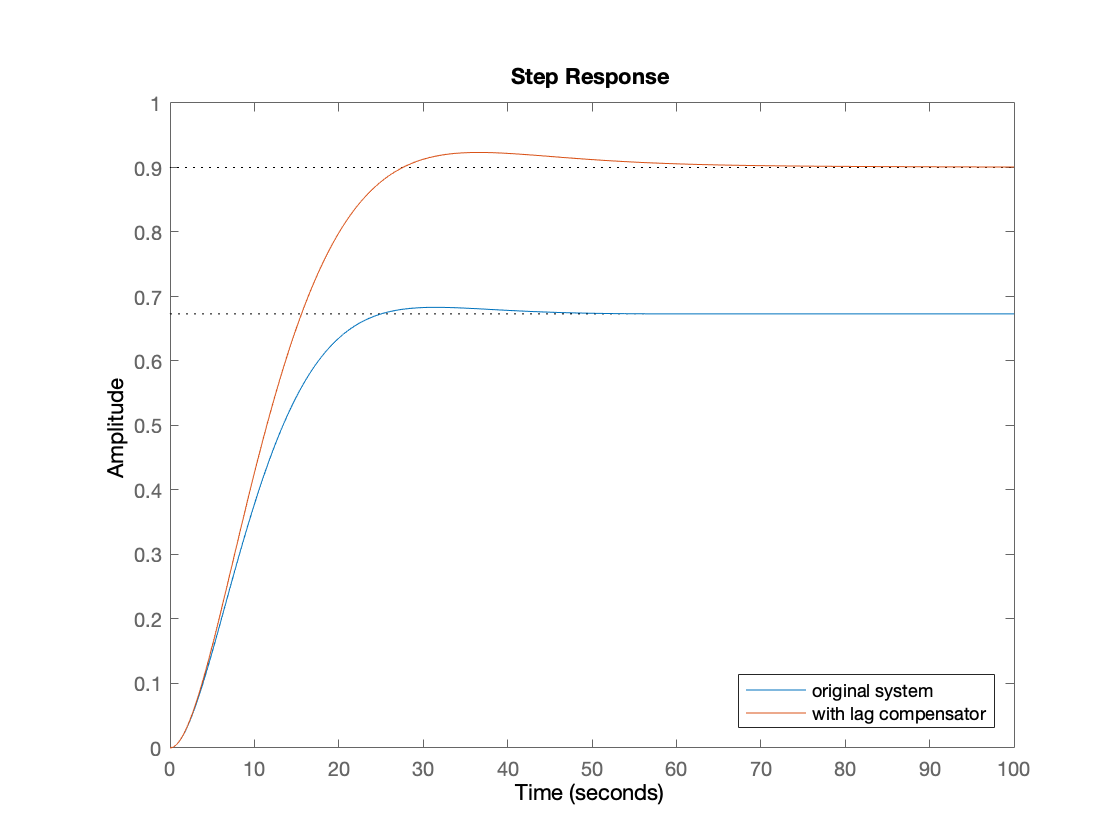

T_lagctrl = feedback(G*Gc,1);
step(T_origin,T_lagctrl)
legend('original system','with lag compensator','Location','southeast')

## Example 2 

Consider the unity-feedback system shown below with open-loop transfer function


$$G(s)=\frac{K}{s(s+1)(s^2+10s+26)}$$


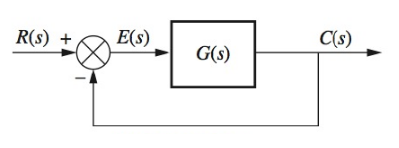

i) Find the settling time for the system if it is operating with 15% OS.

% define the transfer function of the plant %
s = zpk('s');
Gp = 1/(s * (s+1) * (s^2+10*s+26)) 


Gp =
 
             1
  ------------------------
  s (s+1) (s^2 + 10s + 26)
 
Continuous-time zero/pole/gain model.



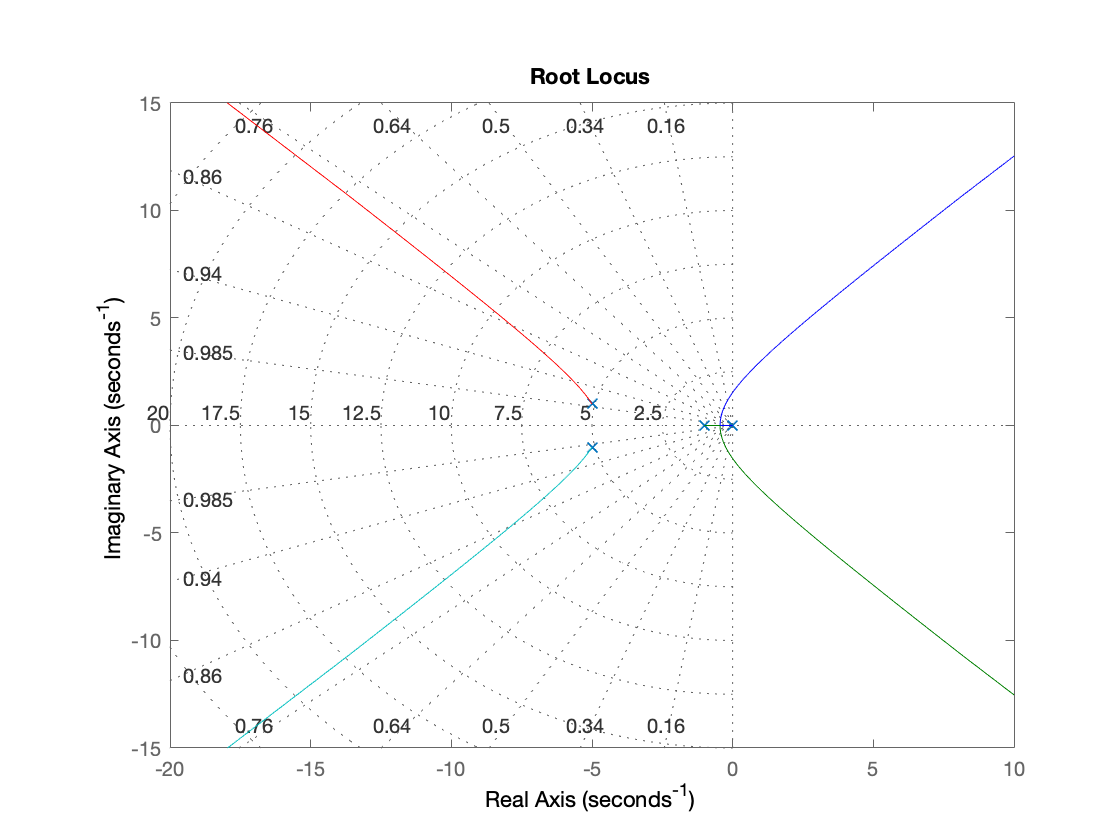

% get the root locus of the plant %
rlocus(Gp)
sgrid

% from root locus the position of close loop pole w/ 15% OS %
p_re = 0.372;                   % real part of the pole
p_im = 0.615;                   % imaginary part of the pole
% find the setting time 
Ts = 4/abs(p_re)

Ts = 10.7527

ii) Develop a cascade cotroller so that the setting time is less than 7s. Specifically, find the zero of the compensator and the gain K, assuming that the pole of the compensator is located at s = -15.

% desired pole position % 
Ts = 7;                         % desired setting time
Po_re = 4/Ts                    % real part of P_desired

Po_re = 0.5714

Po_im = p_im/p_re * Po_re       % imag part of P_desired

Po_im = 0.9447

Po = -Po_re + Po_im*1j          % P_desired

Po =   -0.5714 + 0.9447i


% design the pole & zero of the lead compensator %
Pc = 15;                        % lead controller pole
r2d = 180/pi;                   % radian to degree
ag1 = angle(Po)*r2d             % angle of s

ag1 = 121.1688

ag2 = angle(Po+1)*r2d           % angle of (s+1)

ag2 = 65.5982

ag3 = angle(Po^2+10*Po+26)*r2d  % angle of (s^2+10*s+26)

ag3 = 22.9921

ag4 = angle(Po+Pc)*r2d          % angle of (s+p_c)

ag4 = 3.7461

agu = ag1+ag2+ag3+ag4           % angle of uncompensated system

agu = 213.5052

agz = agu-180                   % compensate angle

agz = 33.5052

Zc =  Po_im/tand(agz) +Po_re    % lead controller zeros

Zc = 1.9984

% design the gain of the lead compensator
Gc = (s+Zc)/(s+Pc);             % Lead compensator without K
G = Gc*Gp


G =
 
             (s+1.998)
  -------------------------------
  s (s+15) (s+1) (s^2 + 10s + 26)
 
Continuous-time zero/pole/gain model.



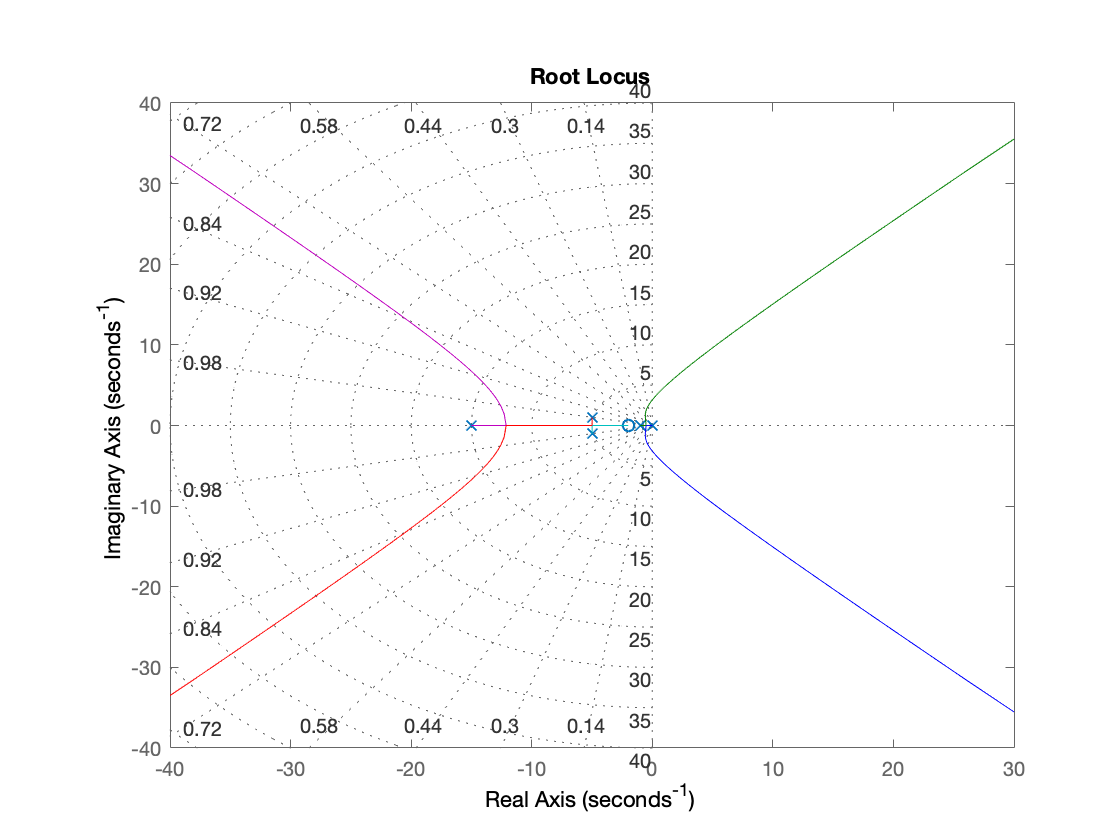

rlocus(G)                       % Root Locus of open-loop system
sgrid

K = 207.512;                    % from RL find the gain
Gc = K*Gc


Gc =
 
  207.51 (s+1.998)
  ----------------
       (s+15)
 
Continuous-time zero/pole/gain model.



iii) Plot the step response of the compensated system and determine the transient response characteristics.

% step response of close-loop system
Gf = Gc*Gp


Gf =
 
         207.51 (s+1.998)
  -------------------------------
  s (s+15) (s+1) (s^2 + 10s + 26)
 
Continuous-time zero/pole/gain model.



T = feedback(Gf,1)


T =
 
                   207.51 (s+1.998)
  --------------------------------------------------
  (s+14.87) (s+6.44) (s+3.549) (s^2 + 1.143s + 1.22)
 
Continuous-time zero/pole/gain model.



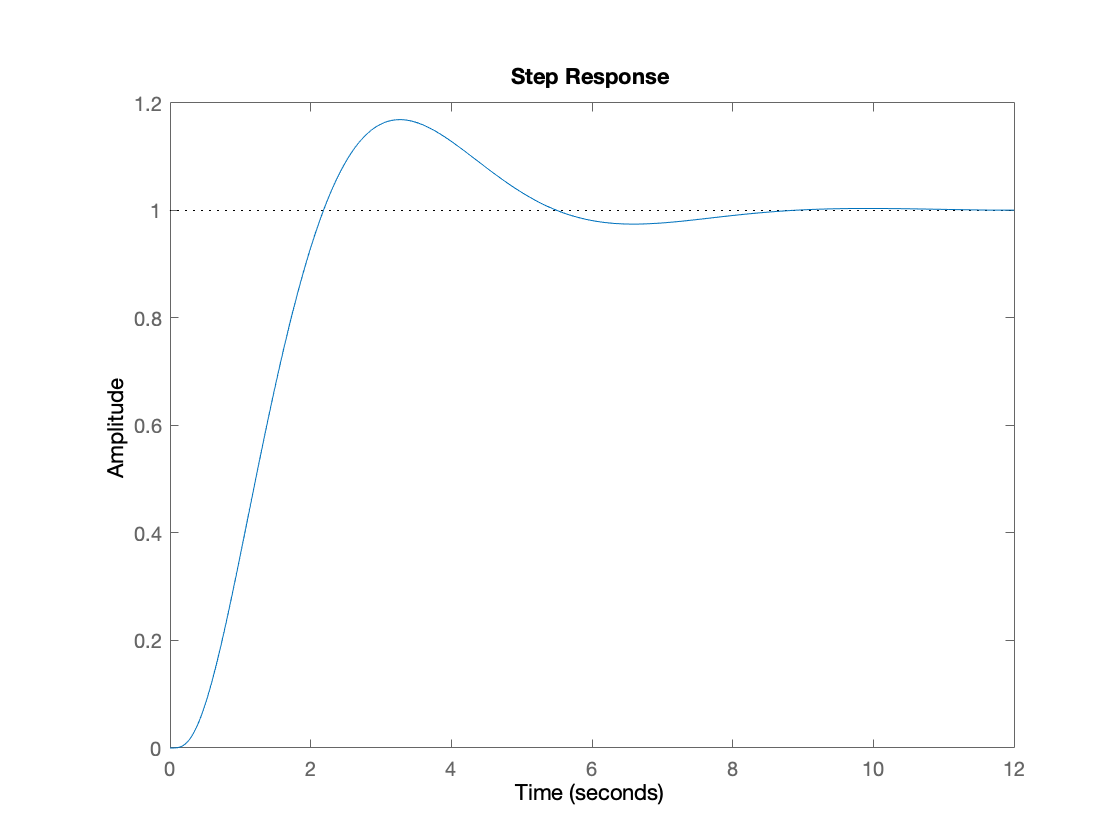

step(T);

stepinfo(T)

ans = struct with fields:
        RiseTime: 1.3846
    SettlingTime: 7.2672
     SettlingMin: 0.9007
     SettlingMax: 1.1690
       Overshoot: 16.9018
      Undershoot: 0
            Peak: 1.1690
        PeakTime: 3.2608


## Exercise 1

Consider the unity feedback system with 


$$G(s)=\frac{K}{(s+1)(s+3)(s+10)}$$


Assume for the remainder of this problem that the system operates with a damping ratio 0.4.

i) Plot the root locus for the system as the gain K is varied

ii) Determine the value of K that will yield a damping ratio 0.4 and determine the corresponding % OS

iii) Determine the steady state error due to a step input for the value of K you found in ii)

iv) Design a PI compensator to drive the step response error to zero while 

maintaining operation with damping ratio 0.4 for the following two cases

a) compensator zero at s=-0.1

b) compensator zero at s=-0.7

v) Compare the specifications of the uncompensated system and each one of the compensated systems(settling time, percent overshoot, steady state error)

vi) Simulate each one of the systems using MATLAB and plot the step response for the uncompensated system and the two compensated systems.

## Exercise 2

Consider the unity feedback system with 


$$G(s)=\frac{K}{(s+4)(s+6)(s+10)}$$


i) Use MATLAB along with hand calculations to design a PID compensator so that the closed-loop system will have % OS <25% and Ts < 2 sec for a step input and zero steady-state error for step and ramp inouts.

ii) Plot the root locus of the compensated system in i) and the step response and show that the specifications are met.